# main.mlx

clc, clear, close all;
datetime("now")

ans = datetime
   15-Oct-2023 23:57:51



for y = 1 : 41
    % расстояние между ядрами в а.е.
    r = 0.45 + 0.05 * y;             

    % Набор базисных коэффициентов
    alpha = [13.00773 1.962079 0.444529 0.1219492 13.00773 1.962079 0.444529 0.1219492];

    % Одно ядро H в начале координат, другое в r
    % расположение атома с i-м базисным коэффициентом
    r_atoms = [0 0 0 0 r r r r];

## Нахождение матричных элементов уравнения Хартри-Фока-Рутана

    % S - матрица перекрывания
    % T - остовной Гамильтониан
    % A - матрица, представляющая двухэлектронные интегралы
    [S, T, A] = find_matrices(alpha, r_atoms, r);

## Нахождение матрицы преобразования

    [V, D] = eig(S);
    for i = 1 : numel(alpha)
        V(:, i) = V(:, i) / (D(i, i) ^ 0.5);
    end
    % V - матрица преобразования

## Нахождение базисных функций из набора STO-4G

    % Базисный набор, построенный из орбиталей типа Слэтера.
    % Орбитали слэтеровского типа — это один из видов базисных функций, используемых в вычислительной химии.
    % Орбитали слэтеровского типа были введены по аналогии с атомными орбиталями в рамках метода МО ЛКАО.
    g = find_the_g(alpha, r_atoms);

## Решение уравнений самосогласованного поля Рутана

    % C - матрица, состоящая из коэффициентов c_mi для i-ой молекулярной
    % орбитали и m-ой атомной орбитали.
    C = ones(1, numel(alpha));
    C = C / (C * S * C');

    % P - матрица плотности / матрица зарядов-порядков связей.
    % Первоначальная догадка.
    P = C' * C;

    % Диапазон в атомных единицах для построения плотности вероятности
    rplot = -2 : 0.01 : 3; 

    % Нахождение волновой функции
    [GndWvFn, C] = fock_matrix(P, T, A, C, g, V, alpha, rplot, r);

    % Взаимодействие атома H и каждого e
    Qs = additional_interaction(g, C);
    % Также добавлено взаимодействие e-e и взаимодействие ядро-ядро
    Eg(y) = 2 * C * (T + A) * C'+ Qs + 1 / r; 
    
    % Корректировка волновой функции
    if Eg(y) == min(Eg)
        WvFnmin = GndWvFn;
    end
end

## График плотности вероятности

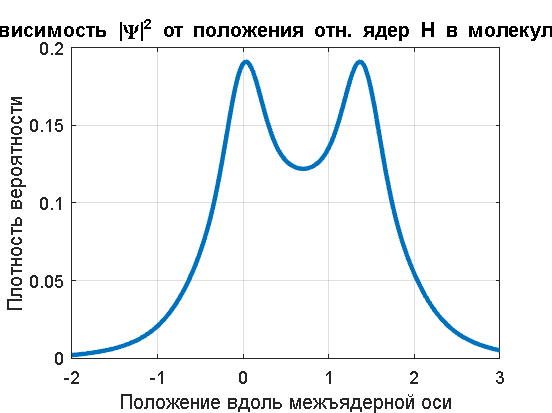

plot(rplot, (abs(WvFnmin)) .^ 2,'LineWidth', 2.5);
xlabel('Положение вдоль межъядерной оси');
ylabel('Плотность вероятности');
title('Зависимость |\Psi|^2 от положения отн. ядер H в молекуле H_2');
grid on;